# **IO751 & IO752 - PROFINET Multi-Node**

The IO751 and IO752-32 are PROFINET I/O modules that are used to connect real-time target machines to industrial equipment. The IO751 is a PROFINET Controller module that is used to communicate with field-level devices such as motor controllers and sensors. The IO752-32 is a PROFINET Device simulation module that is used to simulate devices on the field level in order to test devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. The IO751 acts as one PROFINET station exclusively. The two Ethernet connectors enable easy network integration. The IO752-32 can simulate up to 32 PROFINET Devices.

PROFINET communication typically takes place between one PROFINET Controller and multiple PROFINET Devices. In this example, one controller (IO751) communicates with two devices (two nodes configured on the IO750-32) installed in the same target machine. The IO752-32 simulates the following devices:

- Siemens ET200SP with digital and analog modules attached

- Siemens SINAMICS drive system with one control unit and two motor modules attached

The IO751 is configured to exchange analog and digital values with the simulated ET200SP. The IO751 further controls the SINAMICS drive system by sending speed setpoints and monitoring the actual speed signals.

The IO751 module requires a configuration file (included with this example). The file is created with SYCON.net, a software tool from Hilscher. The IO752-32 is entirely configured in Simulink.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO751 and one IO752-32 installed

- CAT5 Ethernet cable or newer

The IO751 module requires a configuration file. This file comes with the example model and does not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration file. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge.

### Pin Mapping/Connection Diagram/Test Setup

PROFINET is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the IO751 with the IO752-32. The IO751 module has 2 connectors. It does not matter which one you use. Use the leftmost connector on the IO752-32.

The configuration file (*.nxd) for the IO751 is automatically packed into the real-time application by the build process and unpacked during the initialization of the real-time application on the target.

### Explicit PCI addressing

Run the following command in the MATLAB command window:

`>> speedgoat.getIoInterfaces("Advanced", true)`

Identify the IO751 and IO752-32 modules, copy their PCI bus/slot information and paste it to the **PCI Slot** parameter of the corresponding setup blocks in the model.

## Initialize and Open the Simulink model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_IO751_IO752_PROFINETMultiNode';
open_system(modelName);

% Sample time
set_param(modelName, 'StopTime', '10');

## Model Description

The model sets up the communication for both the IO751 and IO752-32. When starting the model, the [IO751 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io751_setup_v2) block loads the corresponding configuration file onto the I/O module. The [IO752-32 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io752_setup_v3) blocks set up the device simulation based on the imported device description files 

- GSDML-V2.33-Siemens-ET200SP-20171124.xml

- GSDML-V2.32-Siemens-Sinamics_S_CU3x0-20160531.xml

which are also included in the example. The Receive and Send blocks are used to exchange data.

The first node of the IO752-32 simulates the ET200SP and its analog and digital modules:

- one digital input module with 8 channels (8 bits)

- one digital output module with 16 channels (16 bits)

- one analog input module with 8 channels (16 bit each)

- one analog output module with 2 channels (16 bit each)

The second node of the IO752-32 simulates the SINAMICS drive and its motor modules. Each motor module provides the following data

- the control word (16 bit)

- the command speed (16 bit)

- the status word (16 bit)

- the actual speed (16 bit)

The IO751 sends the following signals to the IO752-32:

- a uint16 counter sent to the digital output module 

- a sine wave packed in an int16 and sent to the first channel of the analog output module

- the uint16 control word for the first motor module

- the command speed for the first motor module, packed in a uint16 according to the vendor's documentation

- the uint16 control word for the second motor module

- the command speed for the second motor module, packed in a uint16 

The data the IO752-32 receives is logged and output to the scope.

The IO751 receives the following signals from the IO752-32:

- a uint8 counter from the digital input module 

- a sine wave packed in an int16 and received from the first channel of the analog input module

- the uint16 status word from the first motor module

- the actual speed from the first motor module, packed in a uint16 according to the vendor's documentation

- the uint16 status word from the second motor module

- the actual speed from the second motor module, packed in a uint16 according to the vendor's documentation

The data the IO751 receives is logged and output to the scope.

For both motor modules, the control word is simply copied to the status word. The commanded speed is a pulse signal which passes through a motor simulation to compute the actual speed. For motor 1, the system is a PT1 delay, whereas for motor 2, the system is a PT2 delay. 

% Highlight both control systems in the model
 
speedgoat.model.highlight([modelName '/IO752-32 PROFINET Device Simulation/Device 2 SINAMICS/PT1-Delay']);
speedgoat.model.highlight([modelName '/IO752-32 PROFINET Device Simulation/Device 2 SINAMICS/PT2-Delay']);

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('DI');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('DO');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('AI');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('AO');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('Motor_1_CommandSpeed');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('Motor_1_ActualSpeed');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('Motor_2_CommandSpeed');
plotOnSubPlot(s,2,2,true);
s = sdiLatestRun.getSignalsByName('Motor_2_ActualSpeed');
plotOnSubPlot(s,2,2,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-100,10100]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-11,11]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-510,1510]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-510,1510]);

## Check the Results

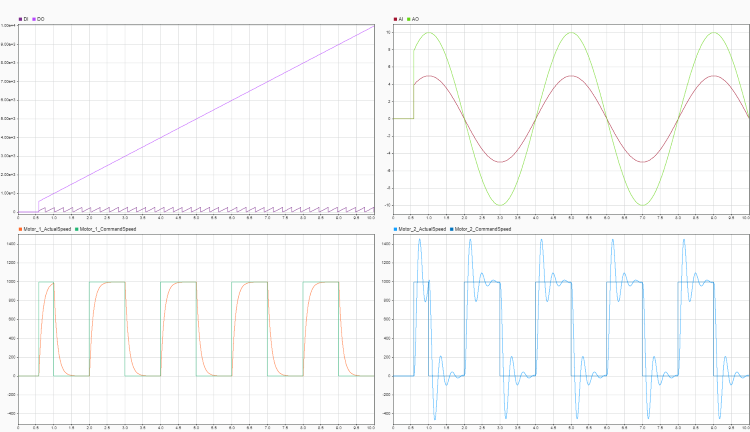

## Additional References

- [IO751 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io751)

- [IO752 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io752)